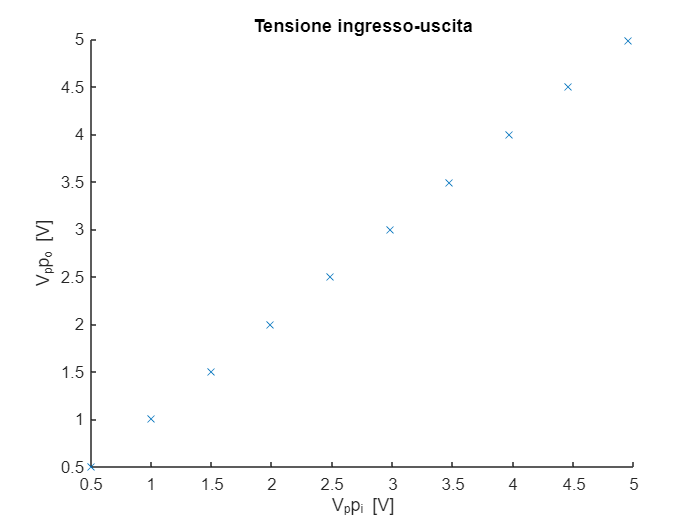

Vpp_i = [0.503 1.000 1.497 1.989 2.486 2.978 3.473 3.965 4.461 4.951];
Vpp_o = [0.505 1.006 1.506 2.002 2.502 3.001 3.496 3.993 4.497 4.985];
figure
hold on
plot(Vpp_i,Vpp_o,'x')
title('Tensione ingresso-uscita')
xlabel('V_pp_i [V]')
ylabel('V_pp_o [V]')

mdl = fitlm(Vpp_i,Vpp_o)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)    -0.0020949      0.001264    -1.6573       0.13604
    x1                 1.0077    0.00041076     2453.3    8.5351e-25


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 0.00184
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 6.02e+06, p-value = 8.54e-25

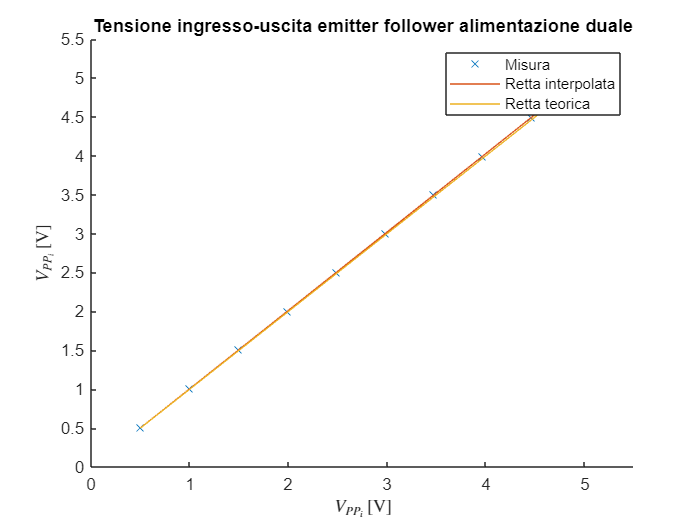

figure
hold on
title('Tensione ingresso-uscita emitter follower alimentazione duale')
xlim([0 5.5])
ylim([0 5.5])
plot(Vpp_i,Vpp_o,'x')
plot([0.5:0.5:5],1.0077.*[0.5:0.5:5]-0.0020949)
plot([0.5:0.5:5],[0.5:0.5:5])
xlabel("$V_{PP_i}$ [V]",'Interpreter','latex')
ylabel("$V_{PP_i}$ [V]",'Interpreter','latex')
legend('Misura', 'Retta interpolata', 'Retta teorica')